clear; close all;

# Cours de Master «Applied Electromagnetism»  

## **Laboratoir Dimensionnement d'antenne Part 1**

### **Antenne FR4**

Caractéristique de l'antenne

Variation de la longeur L2

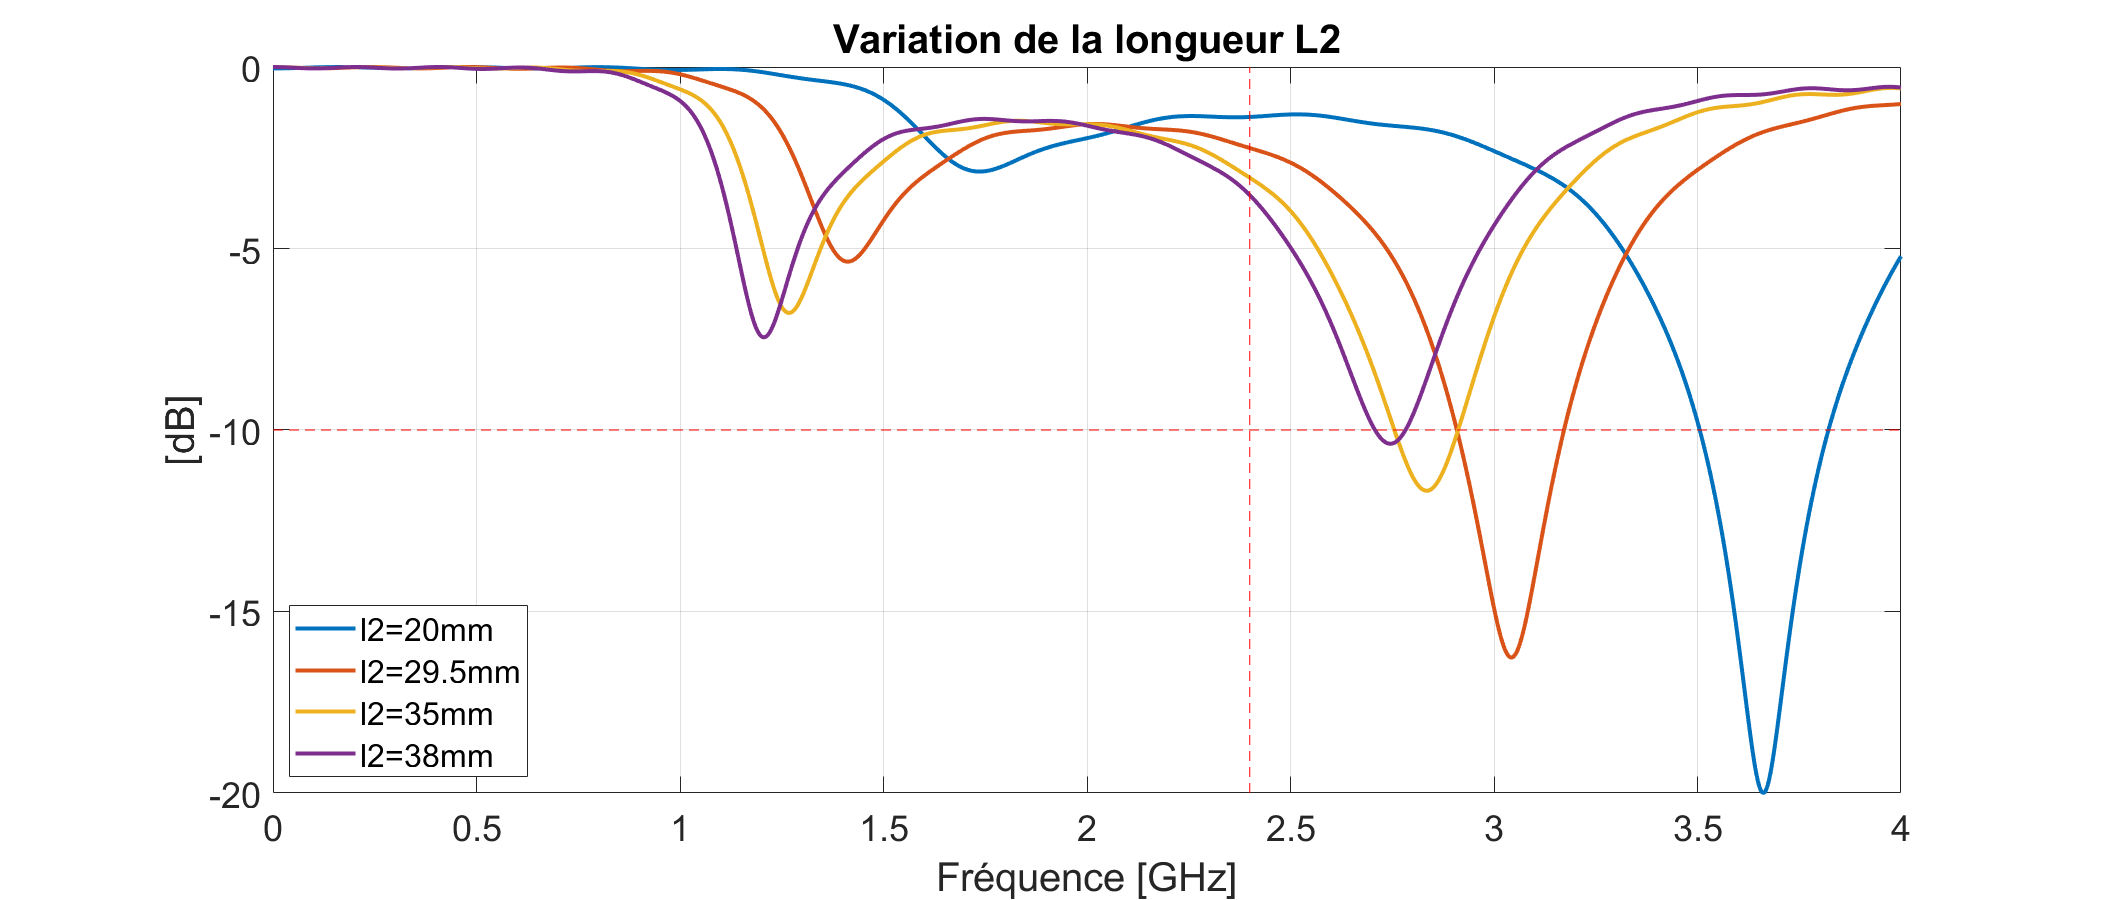

ant1_var_L2_20_0 = importdata('data/FR4/ant1_var_L2_20_0.txt');
ant1_var_L2_29_5 = importdata('data/FR4/ant1_var_L2_29_5.txt');
ant1_var_L2_35_0 = importdata('data/FR4/ant1_var_L2_35_0.txt');
ant1_var_L2_38_0 = importdata('data/FR4/ant1_var_L2_38_0.txt');

f = ant1_var_L2_20_0.data(:,1);
l2_20   = ant1_var_L2_20_0.data(:,2);
l2_29_5 = ant1_var_L2_29_5.data(:,2);
l2_35   = ant1_var_L2_35_0.data(:,2);
l2_38   = ant1_var_L2_38_0.data(:,2);

f1 = figure;
f1.Position = [0 0 1400 600];
plot(f,l2_20,f,l2_29_5,f,l2_35,f,l2_38,"LineWidth",2); hold on;
plot([0 4], [-10 -10], '--r'); 
plot([2.4 2.4], [-20 0], '--r'); 
hold off;
grid on
title('Variation de la longueur L2','FontSize',22)
legend('l2=20mm','l2=29.5mm','l2=35mm','l2=38mm',"Location","southwest");
xlabel('Fréquence [GHz]')
ylabel('[dB]')
set(gca,'FontSize',18)
ylim([-20 0])

Variation de la longeur L1 pour L2 = 38 mm

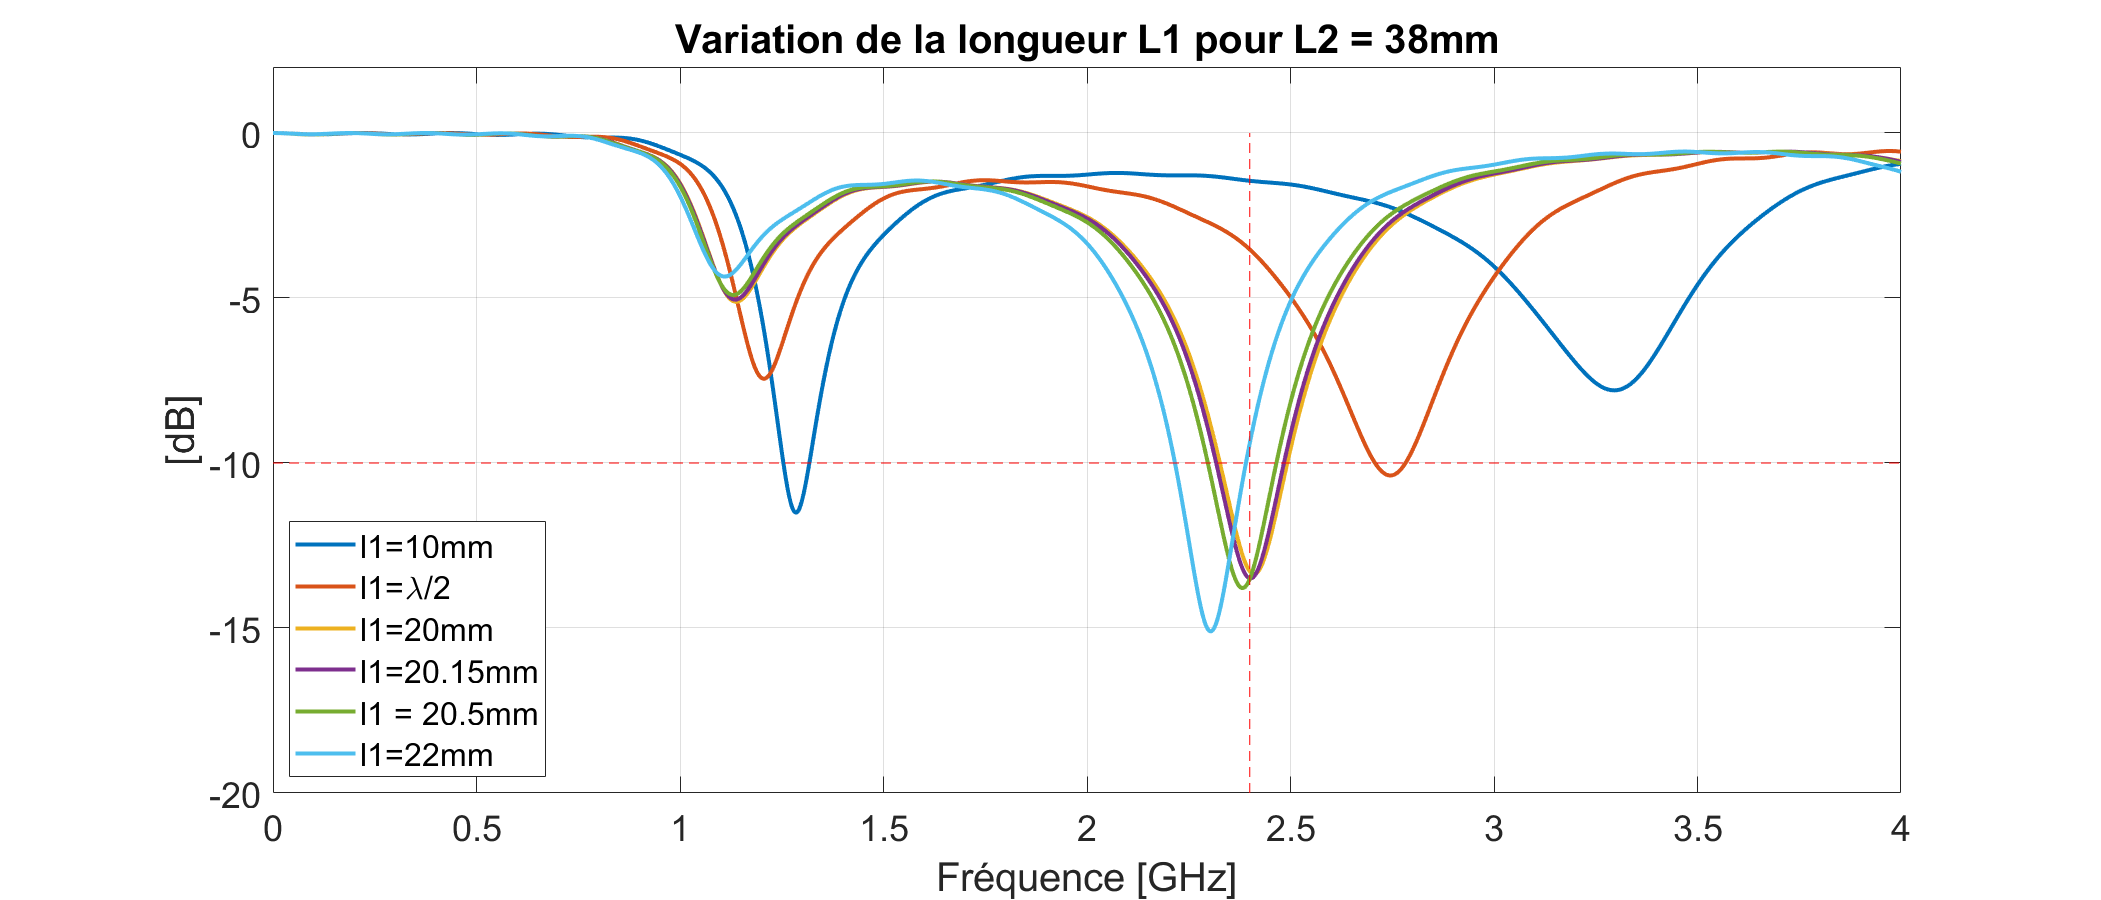

ant1_var_L1_10_0 = importdata('data/FR4/ant1_var_L1_10_0.txt');
ant1_var_L1_20_0 = importdata('data/FR4/ant1_var_L1_20_0.txt');
ant1_var_L1_22_0 = importdata('data/FR4/ant1_var_L1_22_0.txt');
ant1_var_L1_20_5 = importdata('data/FR4/ant1_var_L1_20_5.txt');
ant1_var_L1_20_15 = importdata('data/FR4/ant1_var_L1_20_15.txt');

l1_15    = l2_38;
l1_10    = ant1_var_L1_10_0.data(:,2);
l1_20    = ant1_var_L1_20_0.data(:,2);
l1_22    = ant1_var_L1_22_0.data(:,2);
l1_20_5  = ant1_var_L1_20_5.data(:,2);
l1_20_15  = ant1_var_L1_20_15.data(:,2);

f2 = figure;
f2.Position = [0 0 1400 600];
plot(f,l1_10,f,l1_15,f,l1_20,f,l1_20_15,f,l1_20_5,f,l1_22,"LineWidth",2); hold on;
plot([0 4], [-10 -10], '--r'); 
plot([2.4 2.4], [-20 0], '--r'); 
hold off;
grid on
title('Variation de la longueur L1 pour L2 = 38mm',"FontSize",22)
legend('l1=10mm','l1=\lambda/2','l1=20mm','l1=20.15mm','l1 = 20.5mm','l1=22mm',"Location","southwest");
xlabel('Fréquence [GHz]')
ylabel('[dB]')
set(gca,'FontSize',18)
ylim([-20 2])

Dimention de l'antenne avec substra en FR4 (Lossfree)

l1 = 21 mm

l2 = 38 mm

wl = 2 mm

e = 0.8 mm

Caractéristique des matériaux :

# **Atenne FR4**

## **L1 and L2 parameters tunnig  for **$f_C =2\ldotp 45\;\textrm{GHz}$ and $S_{11} <10\;\textrm{dB}$with $\textrm{wl}=1\ldotp 7\;\textrm{mm}$

## Caractéristiques du substrat 

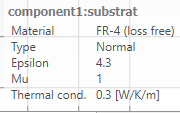

Dimention de l'antenne avec substra en céramique (Alumina 96% Lossfree)

ls = 80 mm

ws = 30 mm

h = 1.6 mm

wl = 1.7 mm

i = 0.8 mm

l1 = 18.8 mm

e = 35e-3 mm

l2 = 21 mm

## Parameters sweep

### Simulate parameters sweeping to notice their influences on the antenna performance

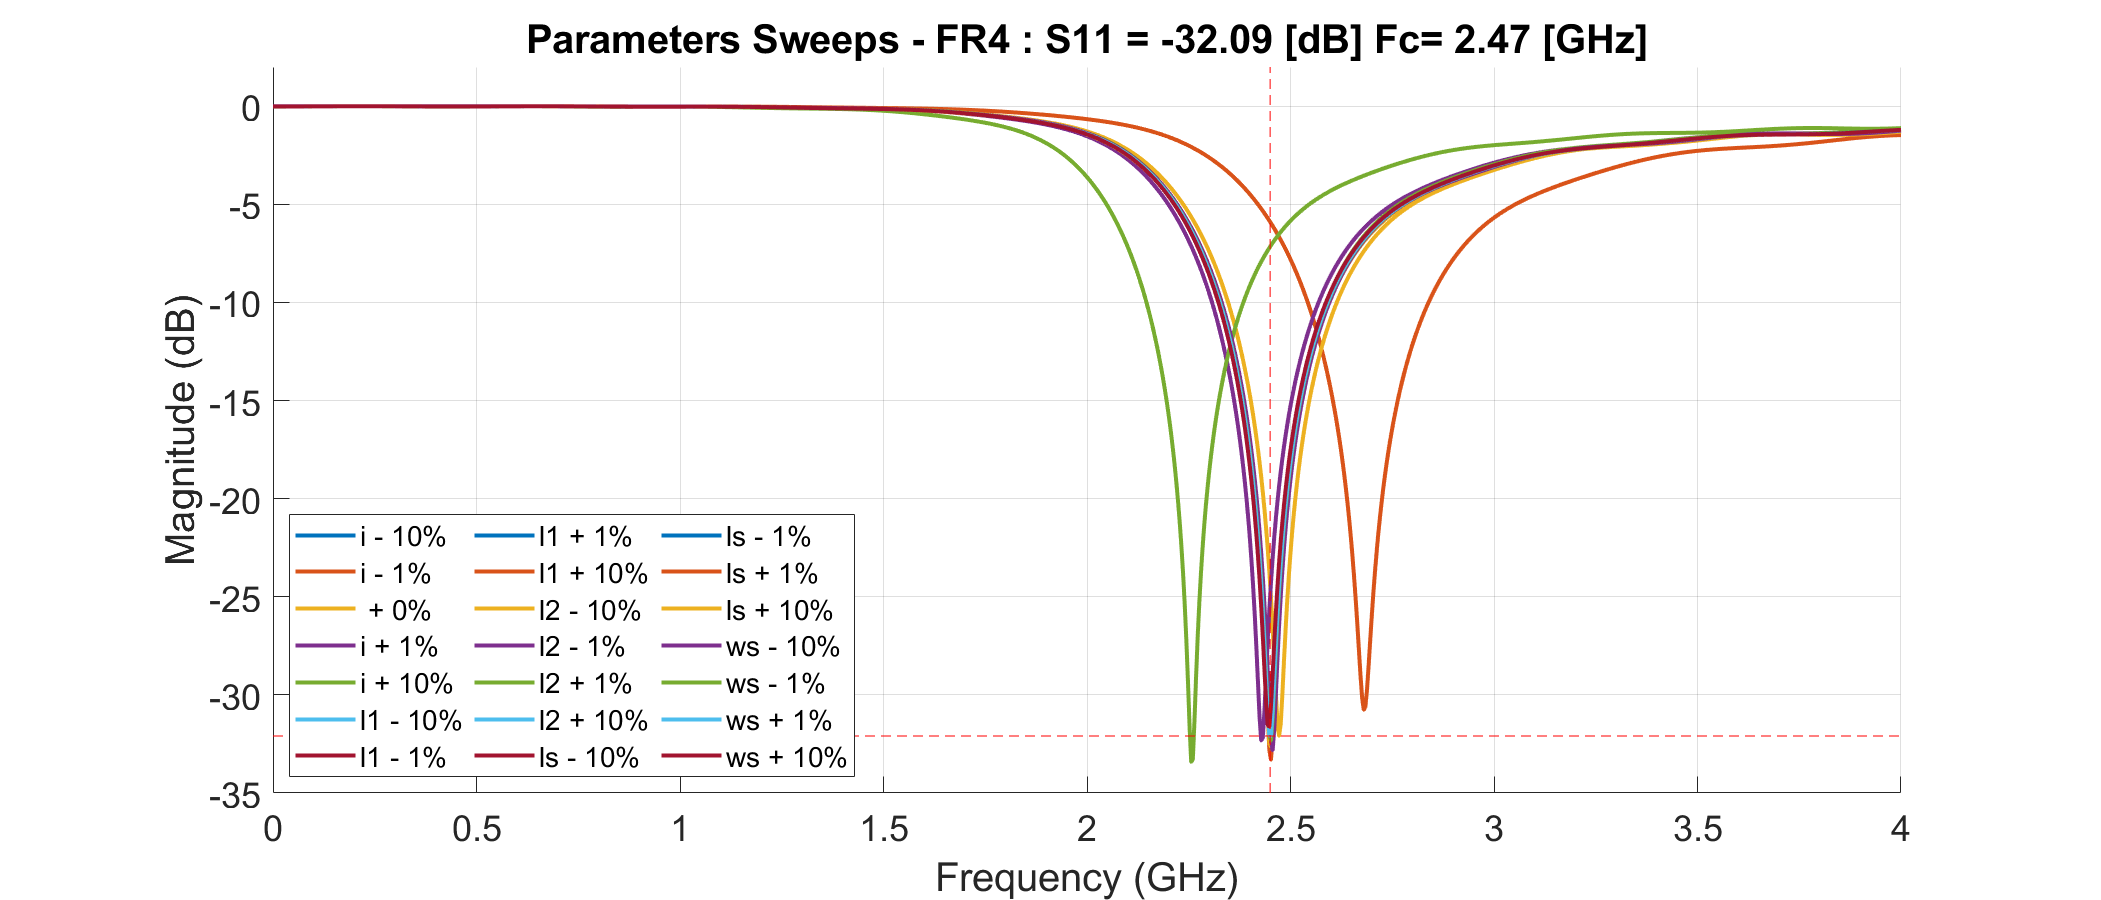

param_sweep_fr4 = importdata("data\FR4\var_sweep\result_navigator.csv", ';');

dir_pos_fr4 = "data\FR4\var_sweep\";
fr4_sweep_nb_files = dir(strcat(dir_pos_fr4,'ant1_fr4_sweep_*'));
var_com_name_fr4 = 'fr4_param_sweep_';

for i=1:length(fr4_sweep_nb_files)
        var_name_fr4 = strcat(var_com_name_fr4,num2str(i));
        var_tab_fr4{i} = var_name_fr4;
        variable.(var_name_fr4) = sparameters(strcat(dir_pos_fr4,fr4_sweep_nb_files(i).name));
end

for k = 1:length(param_sweep_fr4.colheaders)
    param_name_fr4   = string(param_sweep_fr4.colheaders(k));
    param_tab_fr4{k} = param_name_fr4;
    variable.(string(param_name_fr4)) = param_sweep_fr4.data(:,k);
end

sweep_label = ["i - 10%","i - 1%"," + 0%","i + 1%","i + 10%","l1 - 10%","l1 - 1%","l1 + 1%",...
    "l1 + 10%","l2 - 10%","l2 - 1%","l2 + 1%","l2 + 10%","ls - 10%","ls - 1%","ls + 1%",...
    "ls + 10%","ws - 10%","ws - 1%","ws + 1%","ws + 10%"];
N = length(param_sweep_fr4.data(:,1));

f4 = figure;
f4.Position = [0 0 1400 600];
hold on;
for k = 1:length(fr4_sweep_nb_files)
    h = rfplot(variable.(string(var_tab_fr4(k))));
    set(h,'LineWidth',2);
    s11_fr4{k}  = min(h.YData);
    fc_fr4{k}   = h.XData(find(h.YData == s11_fr4{k}));
    bw_temp_fr4 = h.XData(find(h.YData < -10));
    bw_fr4{k}   = (bw_temp_fr4(end)-bw_temp_fr4(1))*1000;
end
plot([2.45 2.45],[-35 2],'--r');
plot([0 4],[cell2mat(s11_fr4(3)) cell2mat(s11_fr4(3))],'--r');
hold off;
grid on
title(sprintf('Parameters Sweeps - FR4 : S11 = %.2f [dB] Fc= %.2f [GHz]',cell2mat(s11_fr4(3)),cell2mat(fc_fr4(3))),"FontSize",22)
legend(sweep_label,"Location","southwest","FontSize",14, "NumColumns",3);
set(gca,'FontSize',18)
ylim([-35 2]);

## Parameter and Performance Comparaison Table 

ID_fr4    = [1:N]';
s11_fr4   = cell2mat(s11_fr4');
ds11_fr4  = 100*(s11_fr4 - s11_fr4(3))/s11_fr4(3);
fc_fr4    = cell2mat(fc_fr4');
dfc_fr4   = 100*(fc_fr4 - fc_fr4(3))/fc_fr4(3);
bw_fr4    = cell2mat(bw_fr4)';
dbw_fr4   = 100*(bw_fr4 - bw_fr4(3))/bw_fr4(3);
T_fr4 = table(ID_fr4,s11_fr4,ds11_fr4,fc_fr4,dfc_fr4,bw_fr4,dbw_fr4,'RowNames',sweep_label, 'VariableNames',...
    {'ID','S11 dB','dS11 %','Fc GHz','dFc %','BW MHz','dBW %'},...
    'DimensionNames',{'Param Sweep','FR4 Performance'});

disp("FR4 Antena Parameter Sweep :")

FR4 Antena Parameter Sweep :


disp(T_fr4)

                ID    S11 dB      dS11 %      Fc GHz     dFc %      BW MHz     dBW % 
                __    _______    _________    ______    ________    ______    _______

    i - 10%      1     -32.19      0.29715    2.452     -0.80906     260      -1.5152
    i - 1%       2    -30.763      -4.1498     2.68       8.4142     292       10.606
    + 0%         3    -32.095            0    2.472            0     264            0
    i + 1%       4    -32.326      0.72114    2.428      -1.7799     260      -1.5152
    i + 10%      5    -33.418       4.1218    2.256      -8.7379     236      -10.606
    l1 - 10%     6    -30.849      -3.8817    2.448     -

## Parameter sweep relative variation for alumina substrat

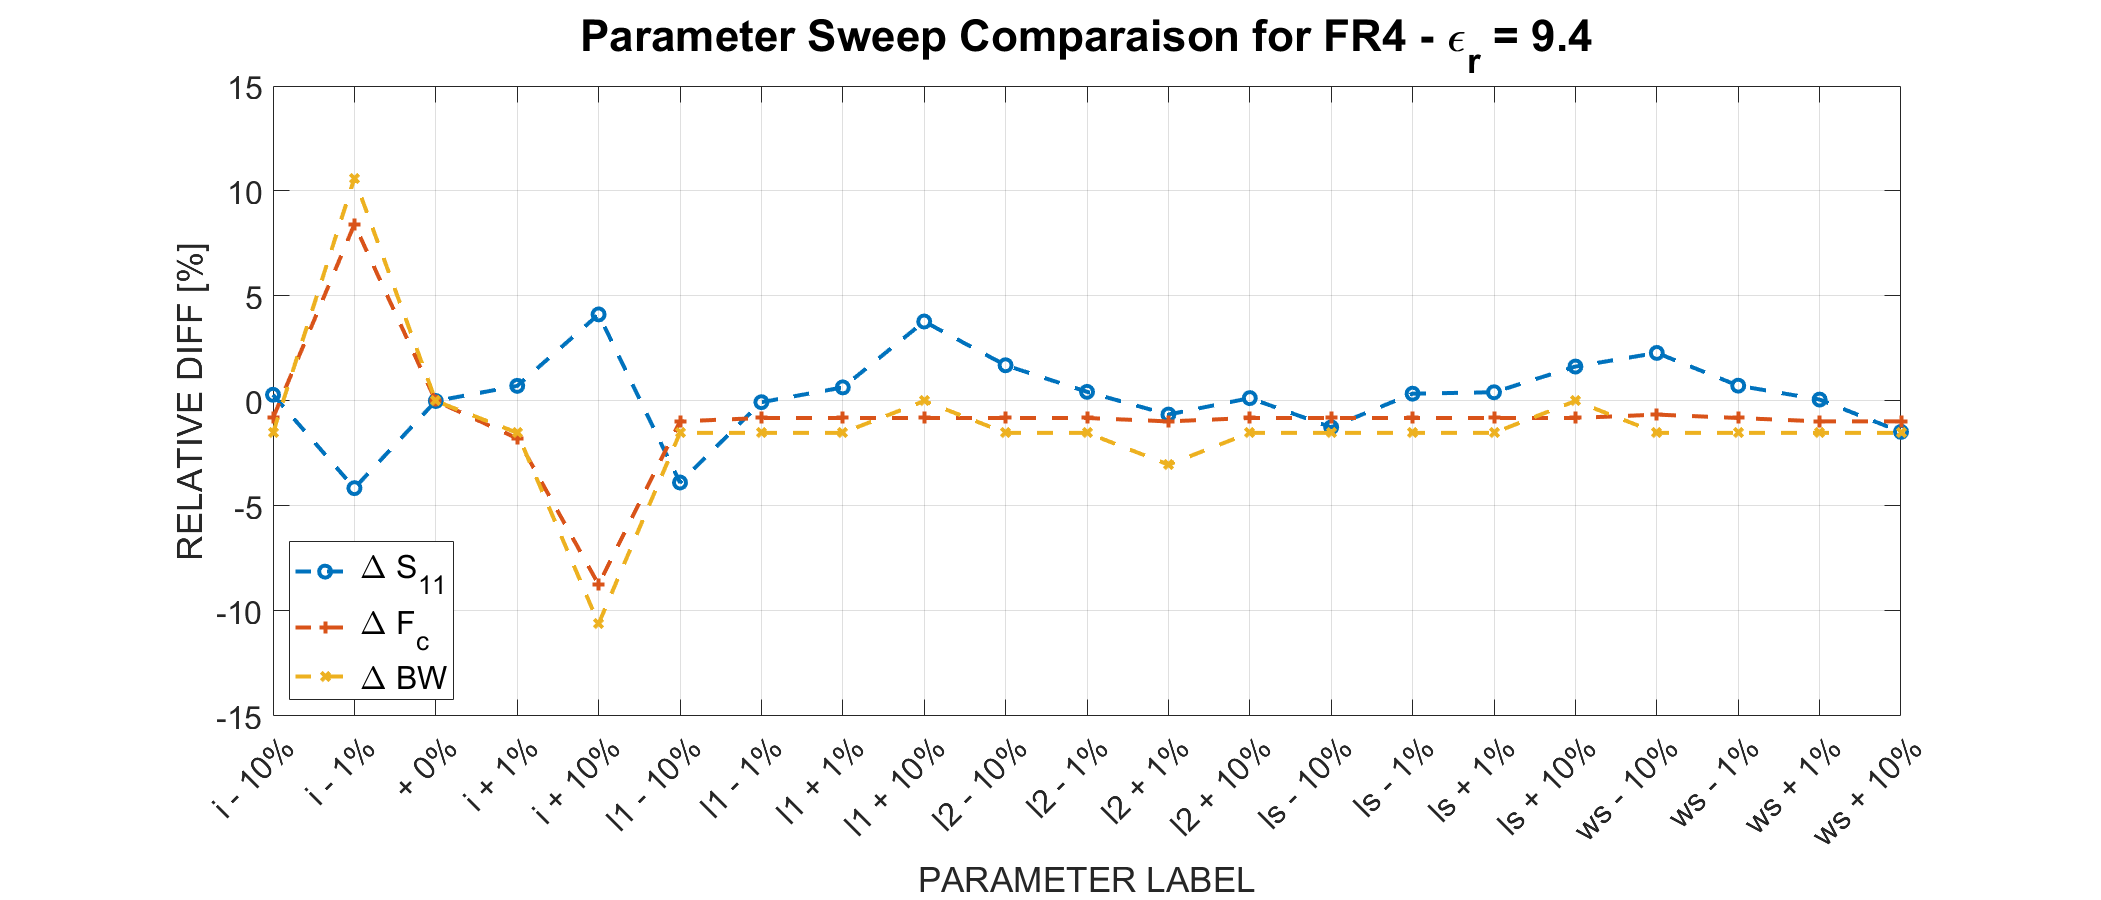

f5 = figure;
f5.Position = [0 0 1400 600];
L = [1:N];
L_name = ["i - 10%","i - 1%"," + 0%","i + 1%","i + 10%","l1 - 10%",...
    "l1 - 1%","l1 + 1%","l1 + 10%","l2 - 10%","l2 - 1%","l2 + 1%",...
    "l2 + 10%","ls - 10%","ls - 1%","ls + 1%","ls + 10%","ws - 10%",...
    "ws - 1%","ws + 1%","ws + 10%"]';

plot(L, ds11_fr4,'--o', L, dfc_fr4,'--+', L, dbw_fr4,'--x', 'linewidth',2); grid on;
legend('\Delta S_{11}','\Delta F_c','\Delta BW',"Location","southwest","FontSize",16, "NumColumns",1);
set(gca,'FontSize',16,'xtick',[1:N],'xticklabel',L_name);
title('Parameter Sweep Comparaison for FR4 - \epsilon_r = 9.4',"FontSize",22);
xlabel('PARAMETER LABEL');
ylabel('RELATIVE DIFF [%]');
xlim([1 N])

## Meilleures performances: ID 17


ID    = param_sweep_fr4.data(17,1);
i     = param_sweep_fr4.data(17,2);
l1    = param_sweep_fr4.data(17,3);
l2    = param_sweep_fr4.data(17,4);
ls    = param_sweep_fr4.data(17,5);
ws    = param_sweep_fr4.data(17,6);

best_fr4_ant_param = [ "ID", "i", "l1", "l2", "ls", "ws" ; ID,i,l1,l2,ls,ws ; "-", "mm", "mm", "mm", "mm", "mm"]';

disp("Best Performing FR4 Antena Parameter :");

Best Performing FR4 Antena Parameter :


disp(best_fr4_ant_param);

    "ID"    "17"       "-" 
    "i"     "0.8"      "mm"
    "l1"    "0.5"      "mm"
    "l2"    "20.96"    "mm"
    "ls"    "88"       "mm"
    "ws"    "30"       "mm"



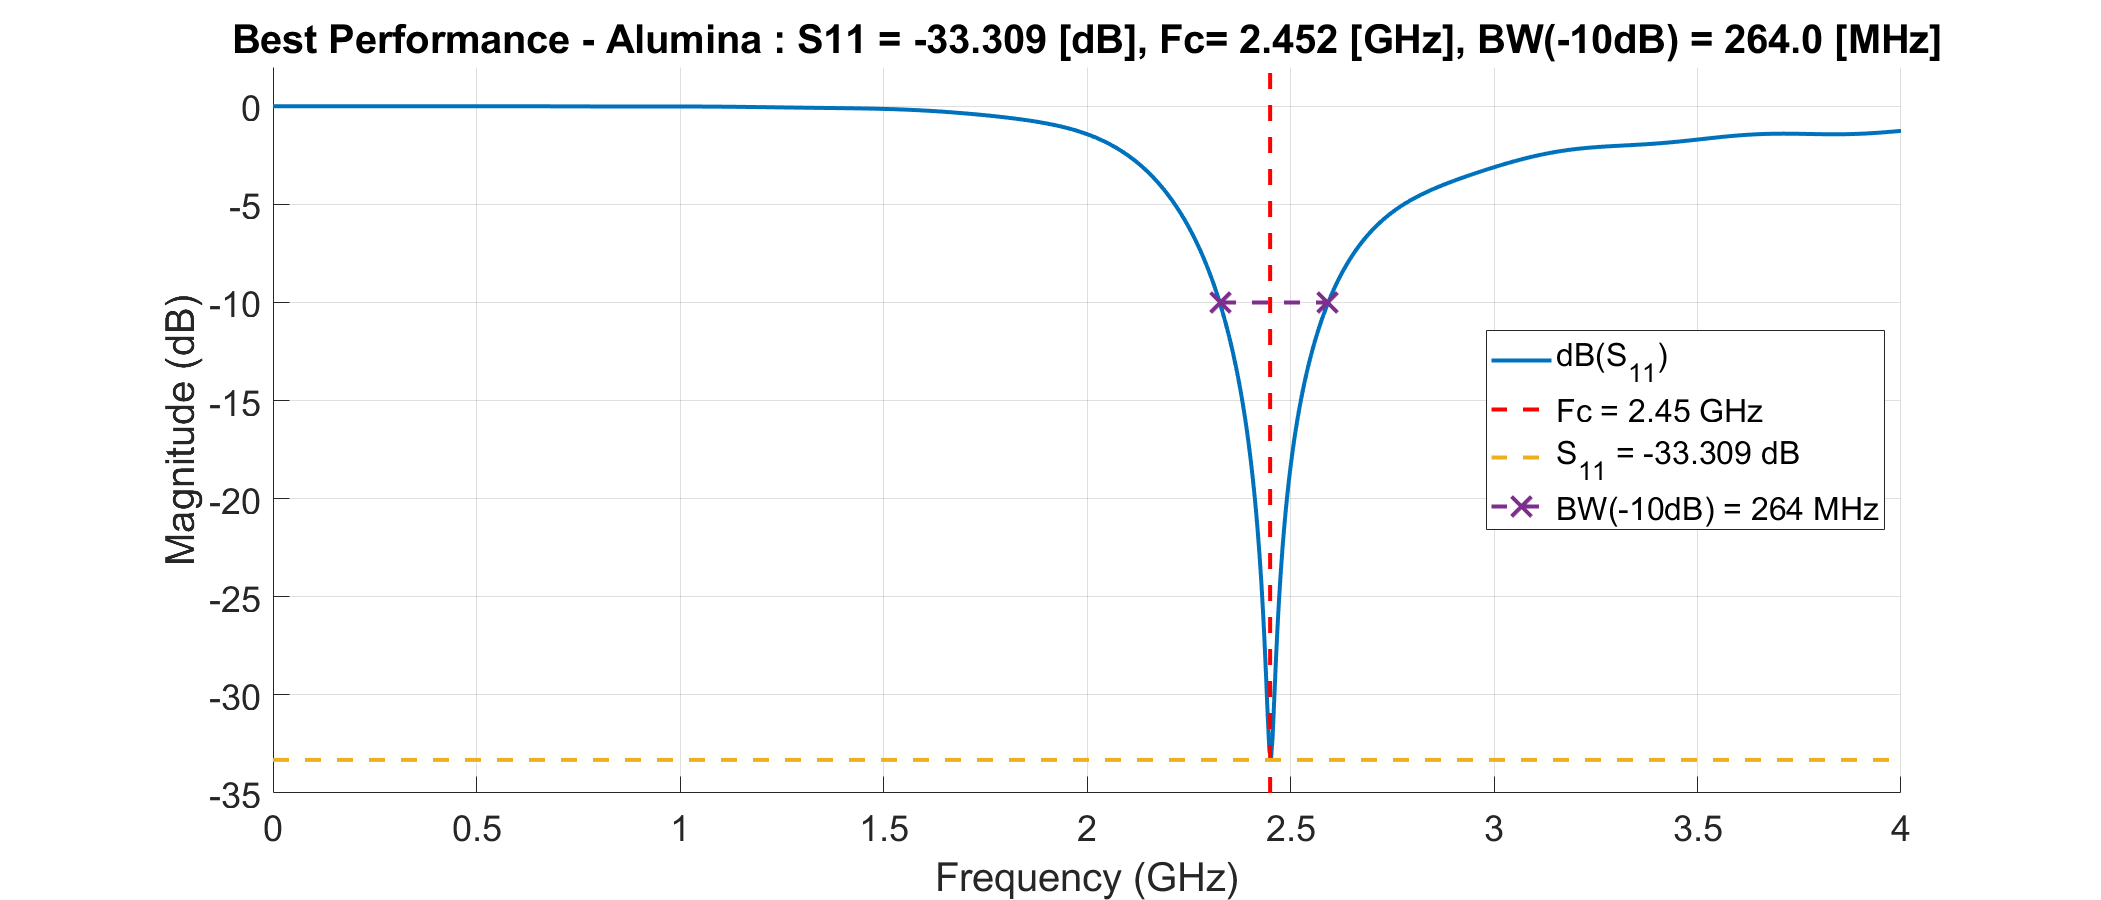

best_perf_fr4 = sparameters('data/FR4/best_perf/ant1_fr4_best_perf.s1p');

f9 = figure;
f9.Position = [0 0 1400 600];
hold on;
    h_fr4 = rfplot(best_perf_fr4);
    set(h_fr4,'LineWidth',2);
    s11_fr4  = min(h_fr4.YData);
    fc_fr4   = h_fr4.XData(find(h_fr4.YData == s11_fr4));
    bw_temp_fr4 = h_fr4.XData(find(h_fr4.YData < -10));
    bw_fr4   = (bw_temp_fr4(end)-bw_temp_fr4(1))*1000;
plot([2.45 2.45],[-35 2],'--r',"LineWidth",2);
plot([0 4],[s11_fr4 s11_fr4],'--',"LineWidth",2);
plot([bw_temp_fr4(1),bw_temp_fr4(end)],[-10 -10],'--X',"LineWidth",2,"MarkerSize",14)
hold off;
grid on
title(sprintf('Best Performance - Alumina : S11 = %.3f [dB], Fc= %.3f [GHz], BW(-10dB) = %.1f [MHz]',s11_fr4,fc_fr4,bw_fr4),"FontSize",22)
legend('dB(S_{11})','Fc = 2.45 GHz', 'S_{11} = -33.309 dB', 'BW(-10dB) = 264 MHz',"Location","east","FontSize",16)
set(gca,'FontSize',18)
ylim([-35 2]);

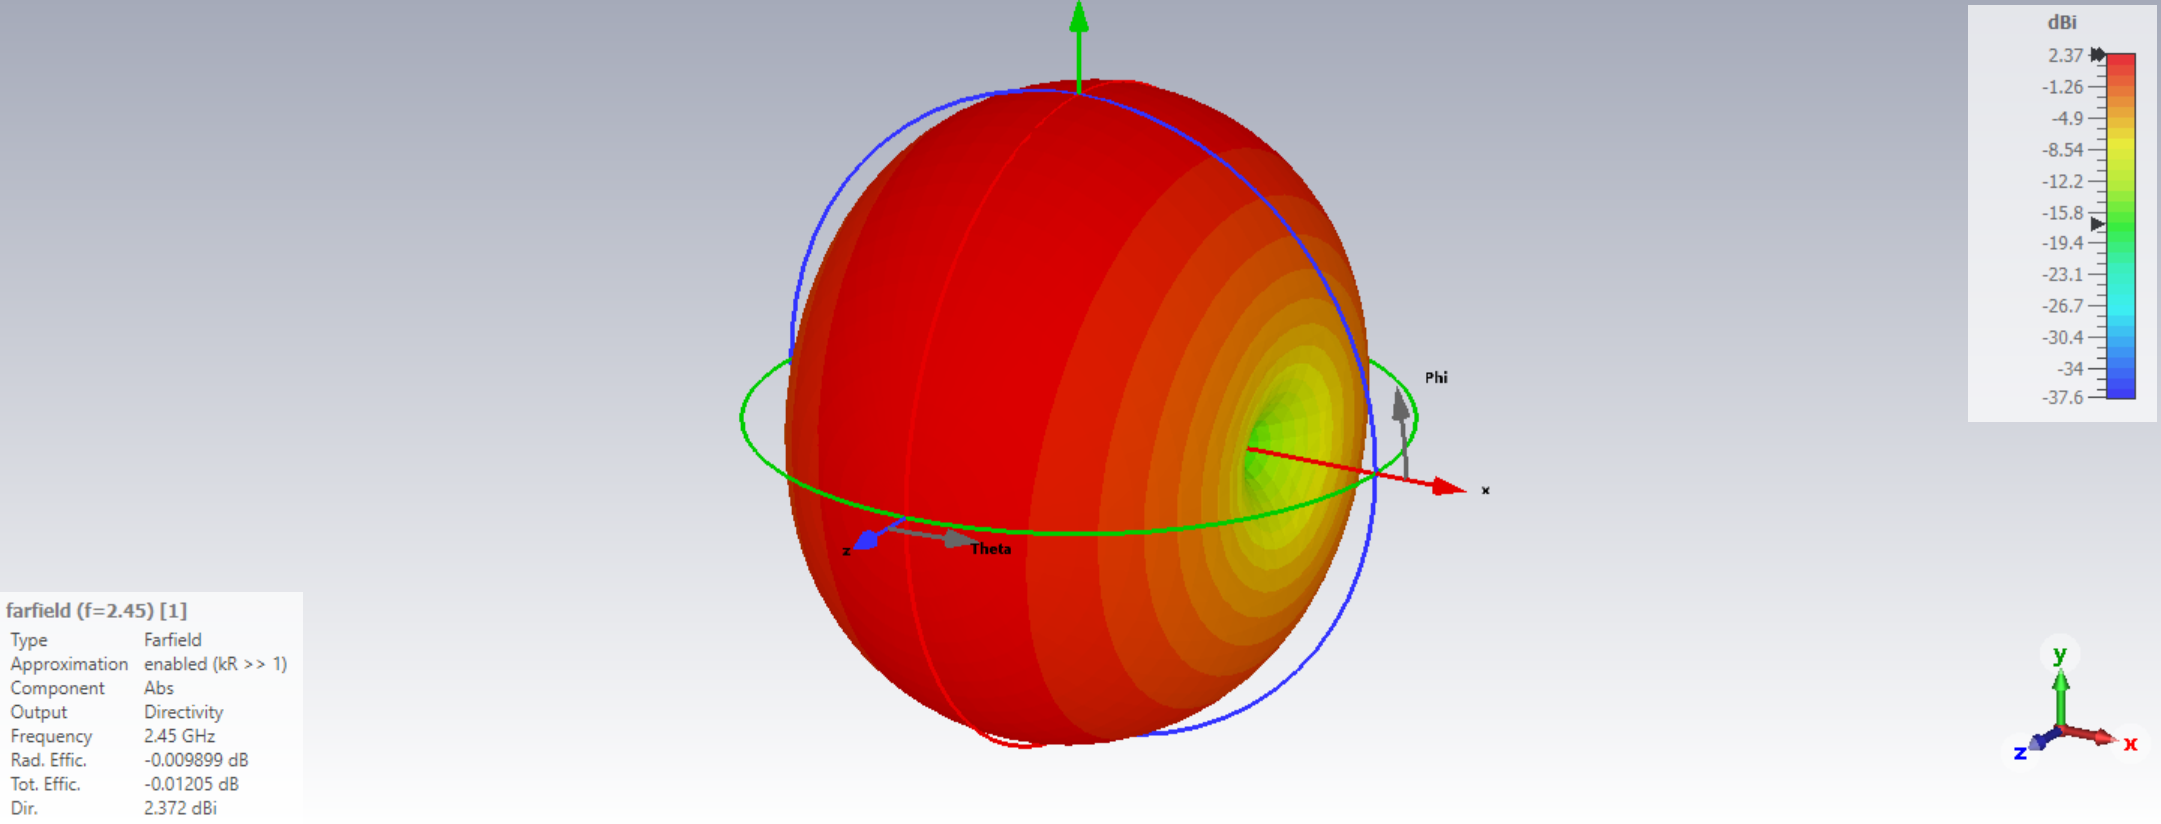

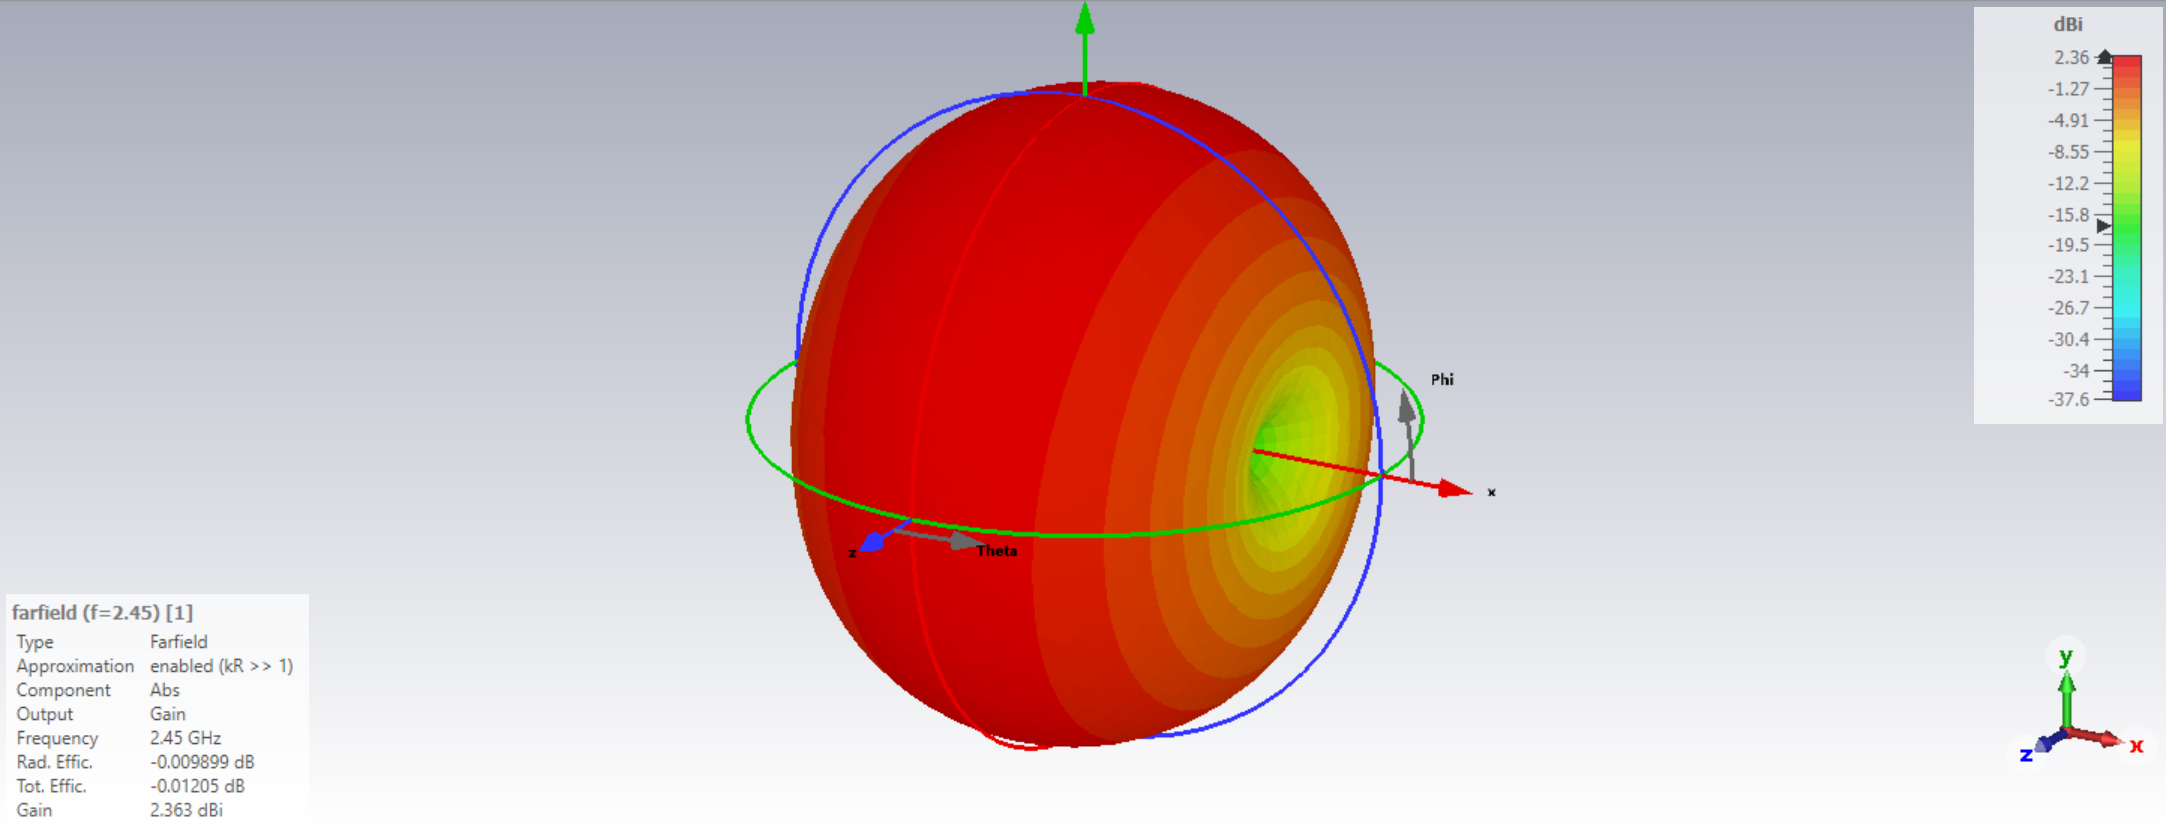

G_fr4      = 2.363;
D_fr4     = 2.372;
etot_fr4   = 100*10^(-0.01205/10);

best_alumin_ant_perf = ["S11","Fc","BW(-10dB)","G","D","e_tot"; s11_fr4,fc_fr4,bw_fr4,G_fr4,D_fr4,etot_fr4 ; "dB", "GHz", "MHz", "dBi", "dBi", "%"]';
disp(best_alumin_ant_perf);

    "S11"          "-33.30935"    "dB" 
    "Fc"           "2.452"        "GHz"
    "BW(-10dB)"    "264"          "MHz"
    "G"            "2.363"        "dBi"
    "D"            "2.372"        "dBi"
    "e_tot"        "99.72292"     "%"  



# **Antenne Ceramique**

## **L1 and L2 parameters tunnig  for **$f_C =2\ldotp 45\;\textrm{GHz}$ and $S_{11} <10\;\textrm{dB}$with $\textrm{wl}=1\ldotp 7\;\textrm{mm}$

## Caractéristiques du substrat 

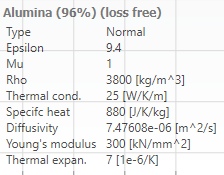

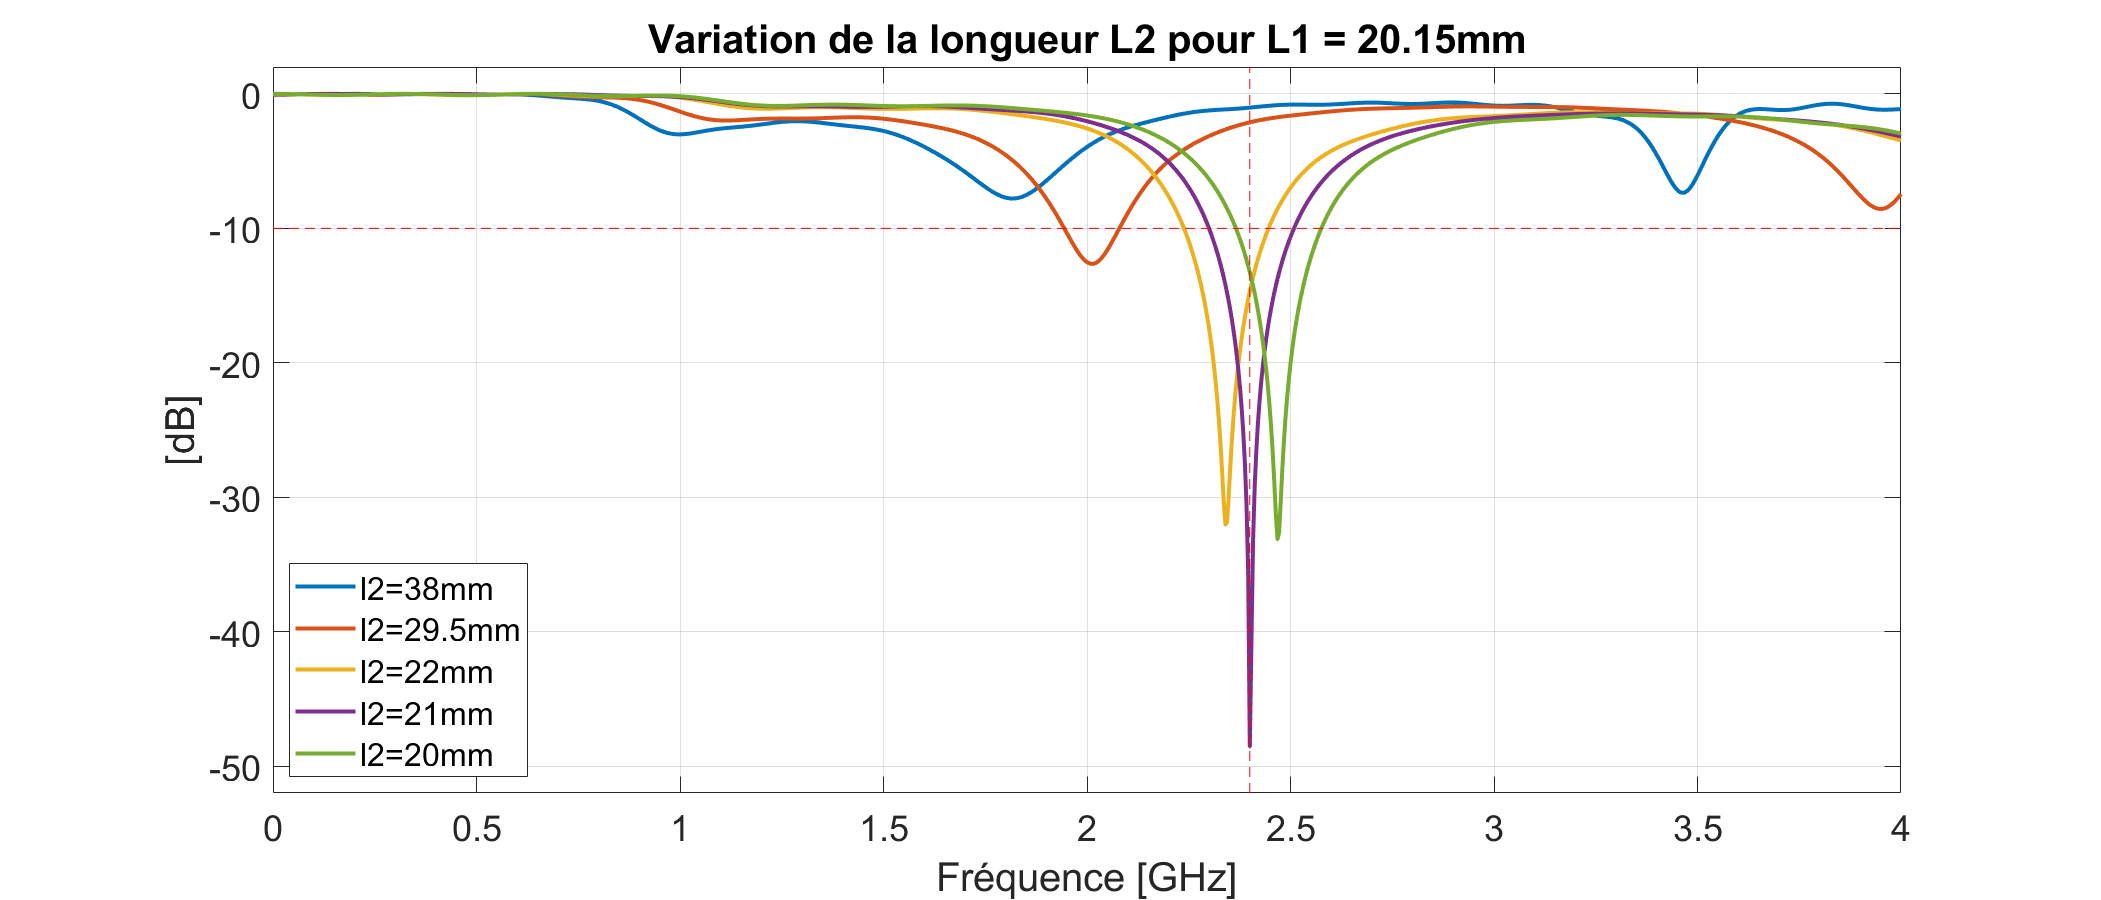

l2_38_2_l1_20_15 = importdata('data/Ceramic/l2_38_2_l1_20_15.txt');
l2_29_5_l1_20_15 = importdata('data/Ceramic/l2_29_5_l1_20_15.txt');
l2_22_0_l1_20_15 = importdata('data/Ceramic/l2_22_0_l1_20_15.txt');
l2_21_0_l1_20_15 = importdata('data/Ceramic/l2_21_0_l1_20_15.txt');
l2_20_0_l1_20_15 = importdata('data/Ceramic/l2_20_0_l1_20_15.txt');


l2_38_0    = l2_38_2_l1_20_15.data(:,2);
l2_29_5    = l2_29_5_l1_20_15.data(:,2);
l2_22_0    = l2_22_0_l1_20_15.data(:,2);
l2_21_0    = l2_21_0_l1_20_15.data(:,2);
l2_20_0    = l2_20_0_l1_20_15.data(:,2);

f2 = figure;
f2.Position = [0 0 1400 600];
plot(f,l2_38_0,f,l2_29_5,f,l2_22_0,f,l2_21_0,f,l2_20_0,"LineWidth",2); hold on;
plot([0 4], [-10 -10], '--r'); 
plot([2.4 2.4], [-52 5], '--r'); 
hold off;
grid on
title('Variation de la longueur L2 pour L1 = 20.15mm',"FontSize",22)
legend('l2=38mm','l2=29.5mm','l2=22mm','l2=21mm','l2=20mm',"Location","southwest");
xlabel('Fréquence [GHz]')
ylabel('[dB]')
set(gca,'FontSize',18)
ylim([-52 2])

Dimention de l'antenne avec substra en céramique (Alumina 96% Lossfree)

ls = 80 mm

ws = 30 mm

h = 1.6 mm

wl = 1.7 mm

i = 0.8 mm

l1 = 18.8 mm

e = 35e-3 mm

l2 = 21 mm

## Parameters sweep

### Simulate parameters sweeping to notice their influences on the antenna performance

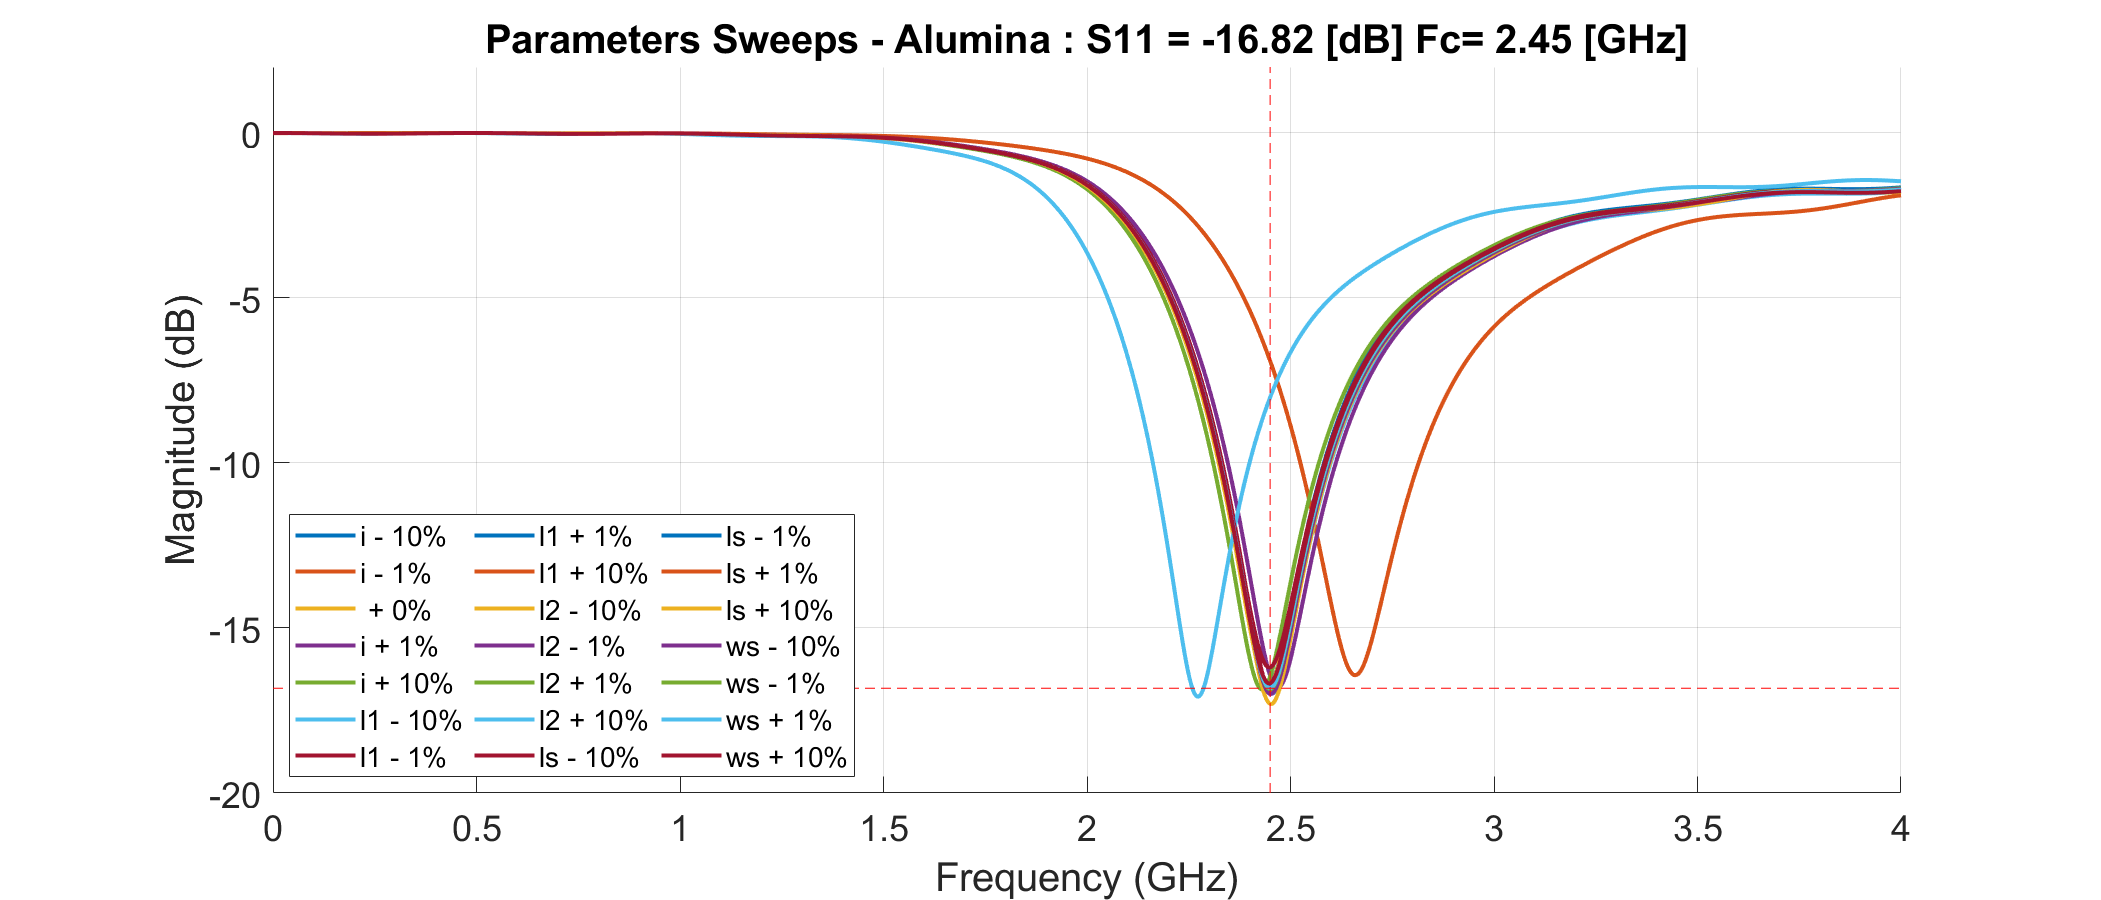

param_sweep = importdata("data\Ceramic\var_sweep\result_navigator.csv", ';');

dir_alumin = "data\Ceramic\var_sweep\";
dir_pos = "data\Ceramic\var_sweep\";
alumin_sweep_nb_files = dir(strcat(dir_pos,'ant1_ceramic_var_sweep*'));
var_com_name = 'alumin_param_sweep_';

for i=1:length(alumin_sweep_nb_files)
        var_name = strcat(var_com_name,num2str(i));
        var_tab{i} = var_name;
        variable.(var_name) = sparameters(strcat(dir_pos,alumin_sweep_nb_files(i).name));
end

for k = 1:length(param_sweep.colheaders)
    param_name   = string(param_sweep.colheaders(k));
    param_tab{k} = param_name;
    variable.(string(param_name)) = param_sweep.data(:,k);
end

sweep_label = ["i - 10%","i - 1%"," + 0%","i + 1%","i + 10%","l1 - 10%","l1 - 1%",...
    "l1 + 1%","l1 + 10%","l2 - 10%","l2 - 1%","l2 + 1%","l2 + 10%","ls - 10%",...
    "ls - 1%","ls + 1%","ls + 10%","ws - 10%","ws - 1%","ws + 1%","ws + 10%"];
N = length(param_sweep.data(:,1));

f4 = figure;
f4.Position = [0 0 1400 600];
hold on;
for k = 1:length(alumin_sweep_nb_files)
    h = rfplot(variable.(string(var_tab(k))));
    set(h,'LineWidth',2);
    s11{k}  = min(h.YData);
    fc{k}   = h.XData(find(h.YData == s11{k}));
    bw_temp = h.XData(find(h.YData < -10));
    bw{k}   = (bw_temp(end)-bw_temp(1))*1000;
end
plot([2.45 2.45],[-20 2],'--r');
plot([0 4],[cell2mat(s11(3)) cell2mat(s11(3))],'--r');
hold off;
grid on
title(sprintf('Parameters Sweeps - Alumina : S11 = %.2f [dB] Fc= %.2f [GHz]',cell2mat(s11(3)),cell2mat(fc(3))),"FontSize",22)
legend(sweep_label,"Location","southwest","FontSize",14, "NumColumns",3);
set(gca,'FontSize',18)
ylim([-20 2]);

## Parameter and Performance Comparaison Table 

ID    = [1:N]';
s11   = cell2mat(s11');
ds11  = 100*(s11 - s11(3))/s11(3);
fc    = cell2mat(fc');
dfc   = 100*(fc - fc(3))/fc(3);
bw    = cell2mat(bw)';
dbw   = 100*(bw - bw(3))/bw(3);
T = table(ID,s11,ds11,fc,dfc,bw,dbw,'RowNames',sweep_label, 'VariableNames',...
    {'ID','S11 dB','dS11 %','Fc GHz','dFc %','BW MHz','dBW %'},...
    'DimensionNames',{'Param Sweep','Antena Performance'});

disp("Alumina Antena Parameter Sweep :")

Alumina Antena Parameter Sweep :


disp(T)

                ID    S11 dB       dS11 %       Fc GHz     dFc %      BW MHz     dBW % 
                __    _______    ___________    ______    ________    ______    _______

    i - 10%      1    -16.683       -0.84429    2.444      -0.1634     252      -3.0769
    i - 1%       2    -16.431        -2.3437     2.66       8.6601     284       9.2308
    + 0%         3    -16.825              0    2.448            0     260            0
    i + 1%       4    -16.836       0.066212    2.448            0     260            0
    i + 10%      5    -16.849        0.14586    2.448            0     260            0
    l1 - 10%     6    -16.994         1.004

## Parameter sweep relative variation for alumina substrat

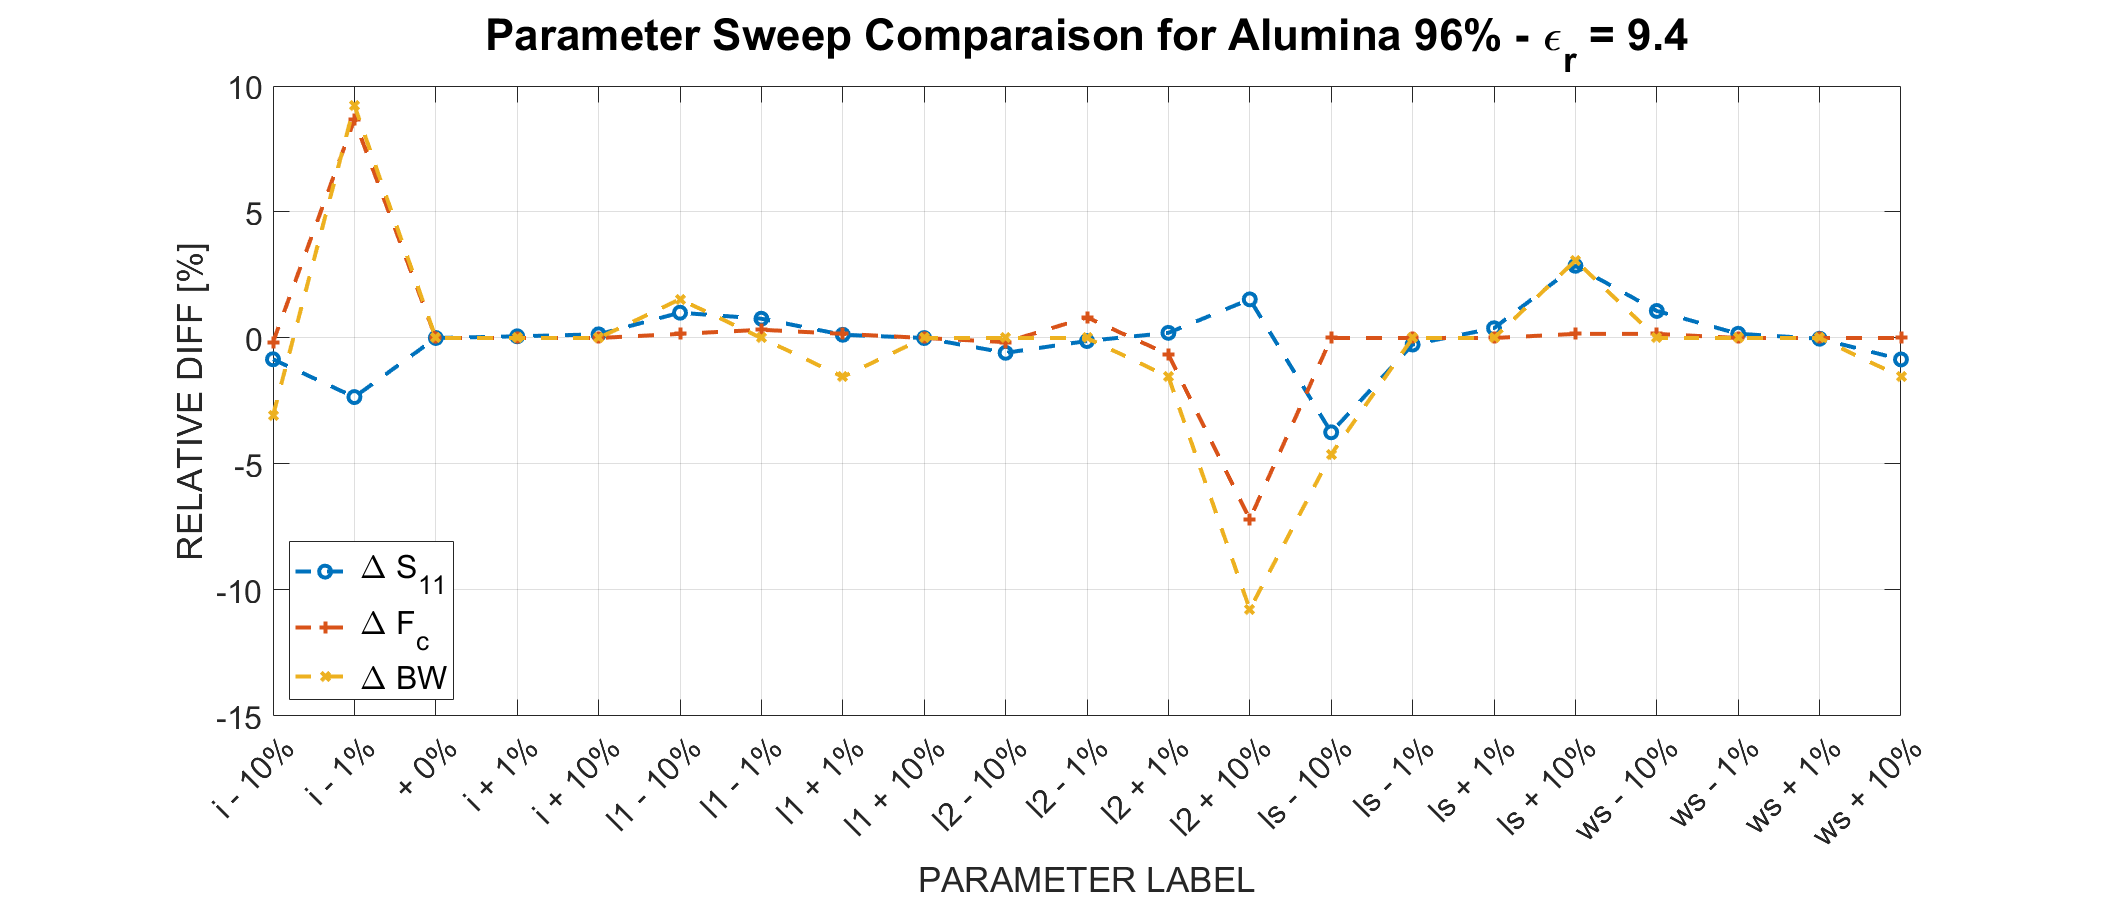

f5 = figure;
f5.Position = [0 0 1400 600];
L = [1:N];
L_name = ["i - 10%","i - 1%"," + 0%","i + 1%","i + 10%","l1 - 10%",...
    "l1 - 1%","l1 + 1%","l1 + 10%","l2 - 10%","l2 - 1%","l2 + 1%",...
    "l2 + 10%","ls - 10%","ls - 1%","ls + 1%","ls + 10%","ws - 10%",...
    "ws - 1%","ws + 1%","ws + 10%"]';

plot(L, ds11,'--o', L, dfc,'--+', L, dbw,'--x', 'linewidth',2); grid on;
legend('\Delta S_{11}','\Delta F_c','\Delta BW',"Location","southwest","FontSize",16, "NumColumns",1);
set(gca,'FontSize',16,'xtick',[1:N],'xticklabel',L_name);
title('Parameter Sweep Comparaison for Alumina 96% - \epsilon_r = 9.4',"FontSize",22);
xlabel('PARAMETER LABEL');
ylabel('RELATIVE DIFF [%]');
xlim([1 N])

## Meilleures performances: ID 17


ID    = param_sweep.data(17,1);
i     = param_sweep.data(17,2);
l1    = param_sweep.data(17,3);
l2    = param_sweep.data(17,4);
ls    = param_sweep.data(17,5);
ws    = param_sweep.data(17,6);

name_param = [];

best_alumin_ant_param = [ "ID", "i", "l1", "l2", "ls", "ws" ; ID,i,l1,l2,ls,ws ; "-", "mm", "mm", "mm", "mm", "mm"]';

disp("Best Performing Alumina Antena Parameter :");

Best Performing Alumina Antena Parameter :


disp(best_alumin_ant_param);

    "ID"    "17"     "-" 
    "i"     "0.8"    "mm"
    "l1"    "0.5"    "mm"
    "l2"    "17"     "mm"
    "ls"    "88"     "mm"
    "ws"    "30"     "mm"



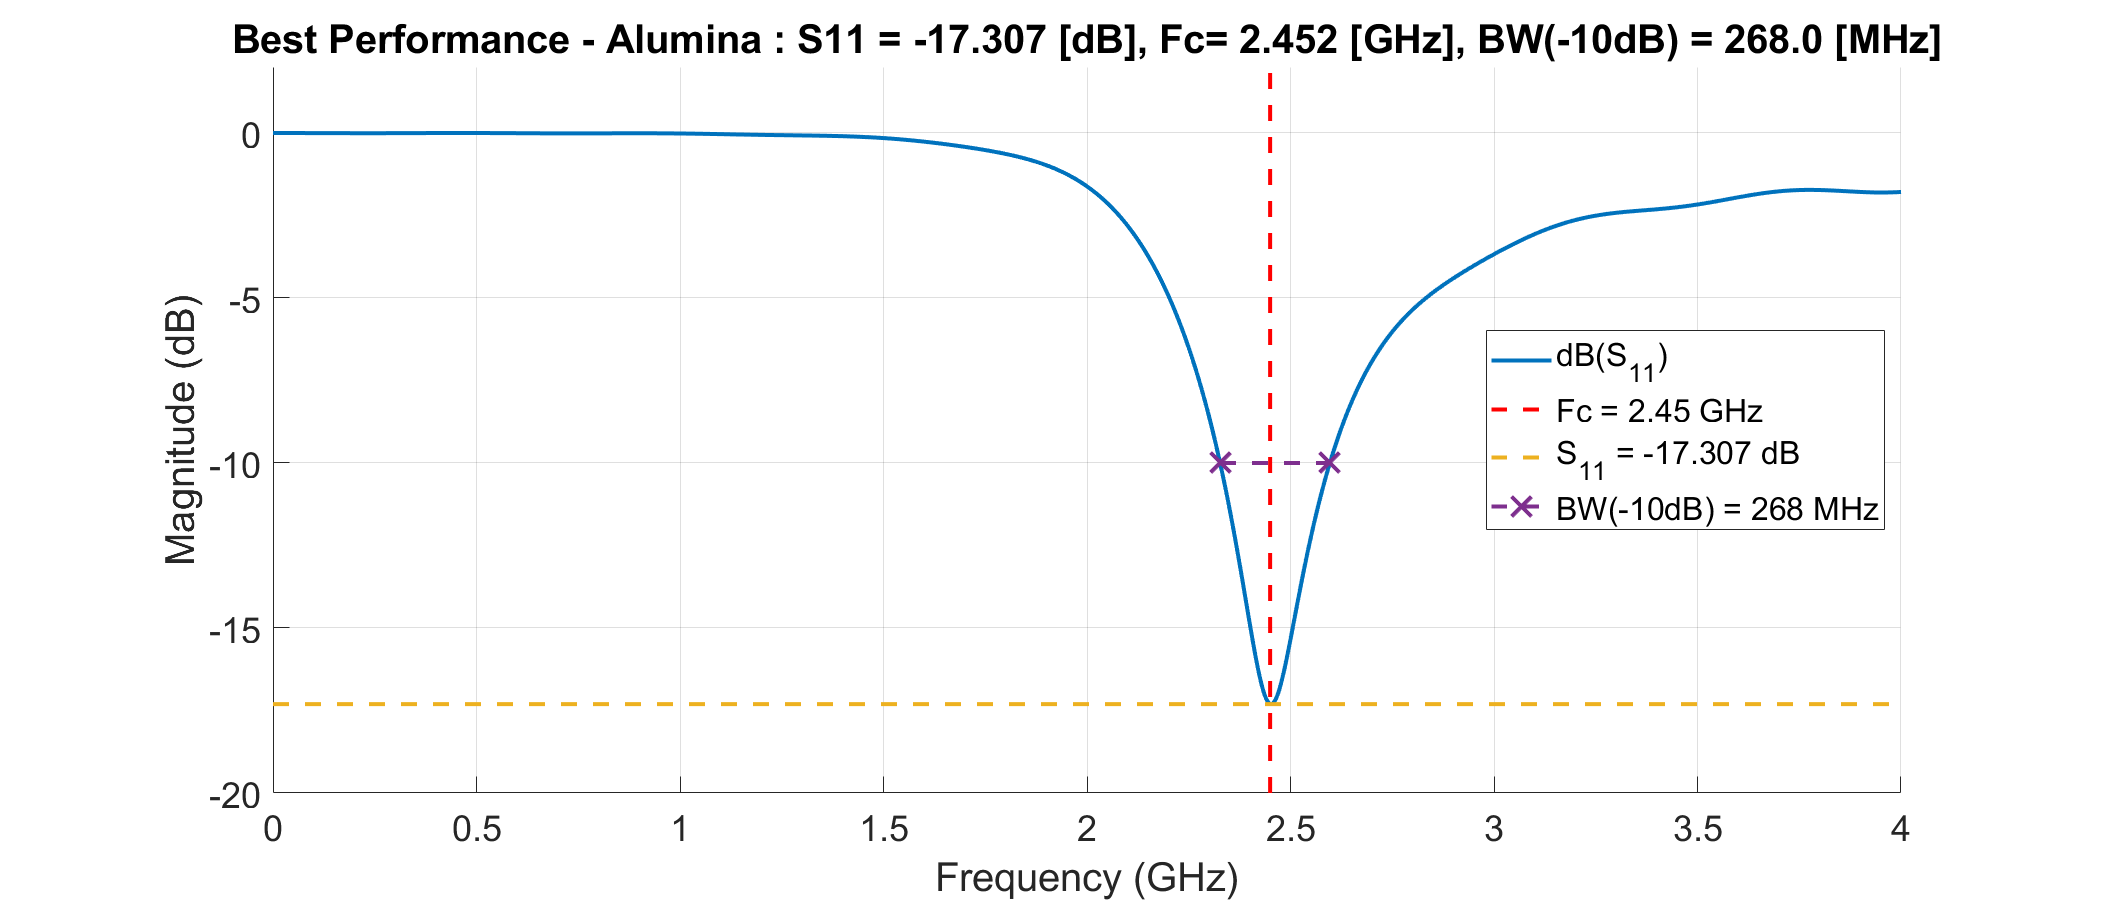

best_perf_alumin = sparameters('data/Ceramic/best_perf/ant1_alumina_best_perf.s1p');

f10 = figure;
f10.Position = [0 0 1400 600];
hold on;
    h = rfplot(best_perf_alumin);
    set(h,'LineWidth',2);
    s11  = min(h.YData);
    fc   = h.XData(find(h.YData == s11));
    bw_temp = h.XData(find(h.YData < -10));
    bw   = (bw_temp(end)-bw_temp(1))*1000;
plot([2.45 2.45],[-20 2],'--r',"LineWidth",2);
plot([0 4],[s11 s11],'--',"LineWidth",2);
plot([bw_temp(1),bw_temp(end)],[-10 -10],'--X',"LineWidth",2,"MarkerSize",14)
hold off;
grid on
title(sprintf('Best Performance - Alumina : S11 = %.3f [dB], Fc= %.3f [GHz], BW(-10dB) = %.1f [MHz]',s11,fc,bw),"FontSize",22)
legend('dB(S_{11})','Fc = 2.45 GHz', 'S_{11} = -17.307 dB', 'BW(-10dB) = 268 MHz',"Location","east","FontSize",16)
set(gca,'FontSize',18)
ylim([-20 2]);

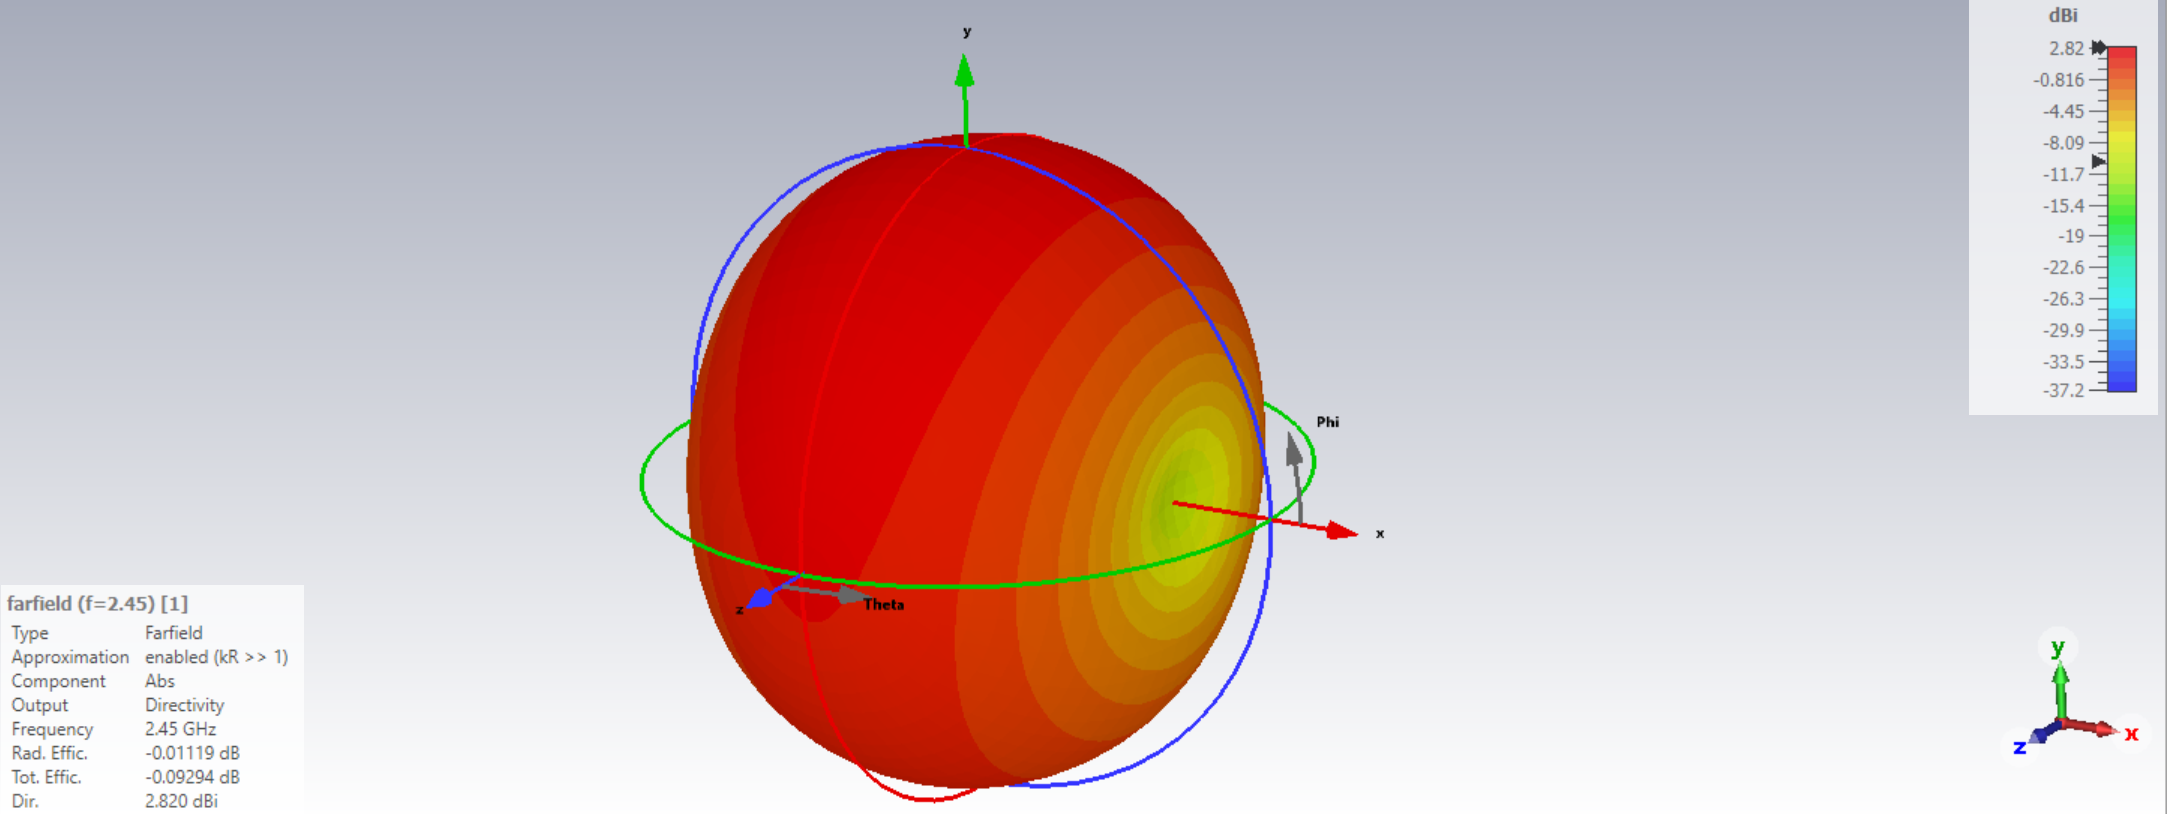

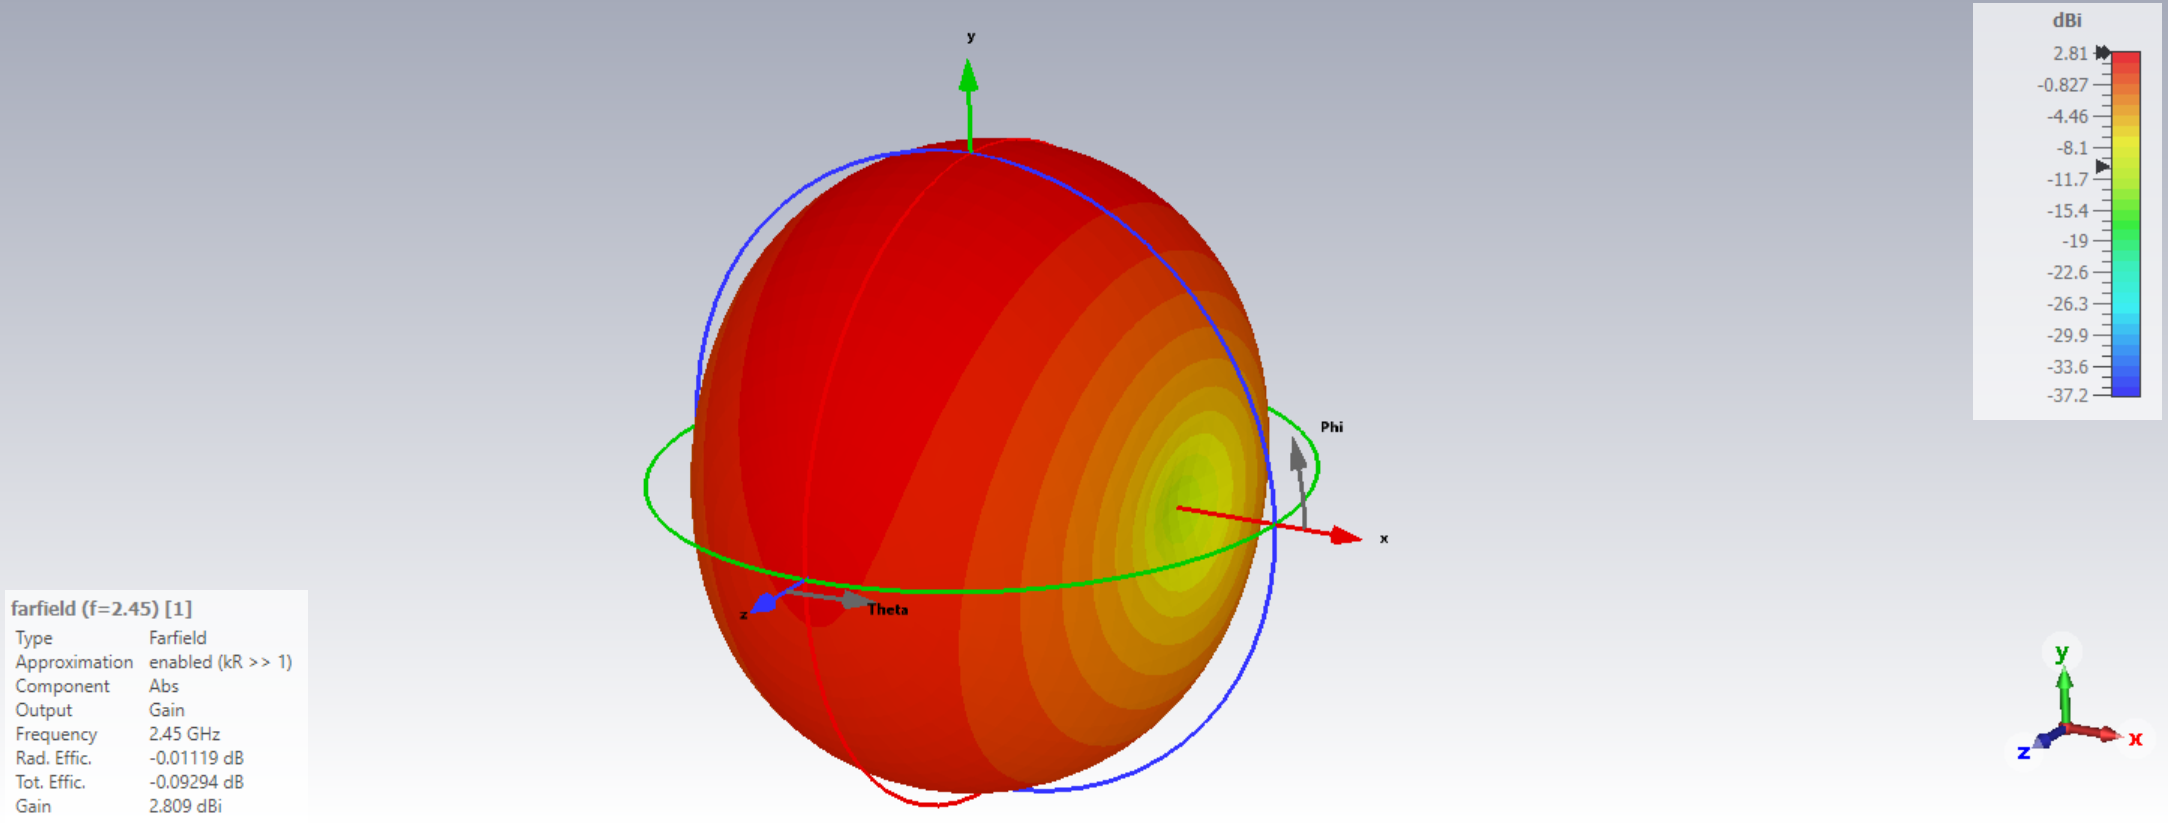

G      = 2.809;
D      = 2.820;
etot   = 100*10^(-0.09294/10);

best_alumin_ant_perf = ["S11","Fc","BW(-10dB)","G","D","e_tot"; s11,fc,bw,G,D,etot ; "dB", "GHz", "MHz", "dBi", "dBi", "%"]';
disp(best_alumin_ant_perf);

    "S11"          "-17.30672"    "dB" 
    "Fc"           "2.452"        "GHz"
    "BW(-10dB)"    "268"          "MHz"
    "G"            "2.809"        "dBi"
    "D"            "2.82"         "dBi"
    "e_tot"        "97.88271"     "%"  

